# ECEN 611 Homework 5: abc to dqn Transformation 

`Shuxuan Chen | 132006082 | Fall 2024`

*Last updated: Oct 20*

clearvars 
clc 

## Problem 1 

A transformation which is sometimes used in the case of synchronous machines, is one where fds leads fqs by 90 degrees with ω=ωr. 

### (a) Express the transformation. 

abc to dq transformation using rotor reference frame 

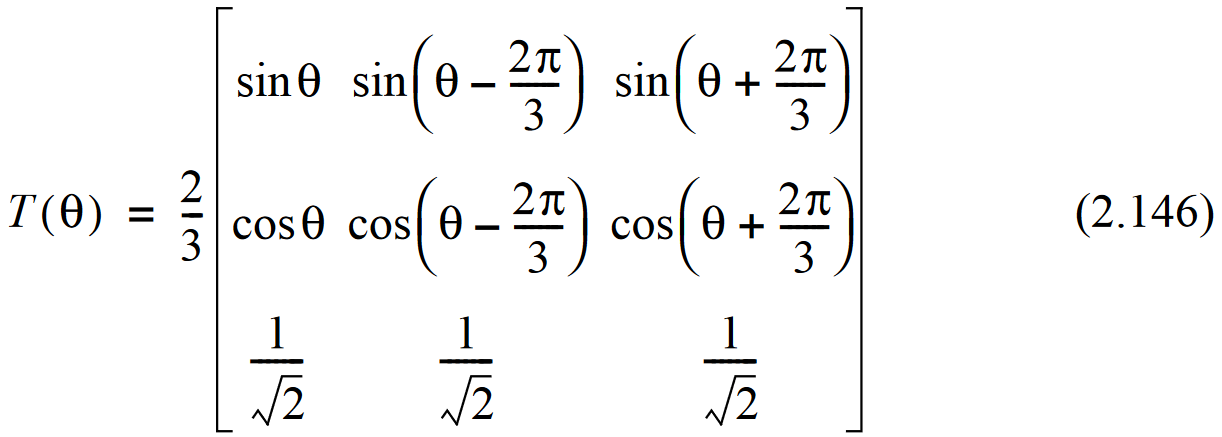

syms T theta
syms omega 
syms omega_r t

angle = [theta theta-2*pi/3 theta+2*pi/3];

T(theta) = [sin(angle);
            cos(angle);
            ones(1,3) * 1/sqrt(2)] * 2/3

$$T(theta) = \left(\begin{array}{ccc} \frac{2\,\sin\left(\theta \right)}{3} & \frac{2\,\sin\left(\theta -\frac{2\,\pi }{3}\right)}{3} & \frac{2\,\sin\left(\theta +\frac{2\,\pi }{3}\right)}{3}\\ \frac{2\,\cos\left(\theta \right)}{3} & \frac{2\,\cos\left(\theta -\frac{2\,\pi }{3}\right)}{3} & \frac{2\,\cos\left(\theta +\frac{2\,\pi }{3}\right)}{3}\\ \frac{\sqrt{2}}{3} & \frac{\sqrt{2}}{3} & \frac{\sqrt{2}}{3} \end{array}\right)$$


T = T(omega*t)

$$T = \left(\begin{array}{ccc} \frac{2\,\sin\left(\omega \,t\right)}{3} & -\frac{2\,\sin\left(\frac{2\,\pi }{3}-\omega \,t\right)}{3} & \frac{2\,\sin\left(\frac{2\,\pi }{3}+\omega \,t\right)}{3}\\ \frac{2\,\cos\left(\omega \,t\right)}{3} & \frac{2\,\cos\left(\frac{2\,\pi }{3}-\omega \,t\right)}{3} & \frac{2\,\cos\left(\frac{2\,\pi }{3}+\omega \,t\right)}{3}\\ \frac{\sqrt{2}}{3} & \frac{\sqrt{2}}{3} & \frac{\sqrt{2}}{3} \end{array}\right)$$


inv_T = simplify(inv(T))

$$inv\_T = \left(\begin{array}{ccc} \sin\left(\omega \,t\right) & \cos\left(\omega \,t\right) & \frac{\sqrt{2}}{2}\\ -\sin\left(\frac{\pi }{3}+\omega \,t\right) & -\cos\left(\frac{\pi }{3}+\omega \,t\right) & \frac{\sqrt{2}}{2}\\ \cos\left(\frac{\pi }{6}+\omega \,t\right) & -\cos\left(\frac{\pi }{3}-\omega \,t\right) & \frac{\sqrt{2}}{2} \end{array}\right)$$

T_times_dinvT_dt = simplify( T * diff(inv_T,t) )

$$T\_times\_dinvT\_dt = \left(\begin{array}{ccc} 0 & -\omega & 0\\ \omega & 0 & 0\\ 0 & 0 & 0 \end{array}\right)$$

dT_dt_times_inv_T = simplify( diff(T,t) * inv_T )

$$dT\_dt\_times\_inv\_T = \left(\begin{array}{ccc} 0 & \omega & 0\\ -\omega & 0 & 0\\ 0 & 0 & 0 \end{array}\right)$$


disp("Transformation from abc to rotor reference frame is: ")

Transformation from abc to rotor reference frame is: 


Tr = subs(T, omega, omega_r)

$$Tr = \left(\begin{array}{ccc} \frac{2\,\sin\left(\omega_{r}\,t\right)}{3} & -\frac{2\,\sin\left(\frac{2\,\pi }{3}-\omega_{r}\,t\right)}{3} & \frac{2\,\sin\left(\frac{2\,\pi }{3}+\omega_{r}\,t\right)}{3}\\ \frac{2\,\cos\left(\omega_{r}\,t\right)}{3} & \frac{2\,\cos\left(\frac{2\,\pi }{3}-\omega_{r}\,t\right)}{3} & \frac{2\,\cos\left(\frac{2\,\pi }{3}+\omega_{r}\,t\right)}{3}\\ \frac{\sqrt{2}}{3} & \frac{\sqrt{2}}{3} & \frac{\sqrt{2}}{3} \end{array}\right)$$

### (b) Using this transformation, write the voltage equations for a 3-phase inductive circuit.

Following

We can derive 


$$\begin{array}{l}
v_{\mathrm{dqns}} =L_s \,M\,\frac{\partial }{\partial t}\mathrm{\ }i_{\mathrm{abcs}} =L_s \left\lbrack \frac{\partial }{\partial t}\ \left(Mi_{\mathrm{abcs}} \right)-\frac{\partial M}{\partial t}i_{\mathrm{abcs}} \right\rbrack \\
=\;L_s \left\lbrack \frac{\partial }{\partial t}\ i_{\mathrm{dqns}} -\frac{\partial M}{\partial t}{\left(M^{-1} M\right)\;i}_{\mathrm{abcs}} \right\rbrack \\
=L_s \left\lbrack \frac{\partial }{\partial t}\ i_{\mathrm{dqns}} -\frac{\partial M}{\partial t}M^{-1} \left(M\;i_{\mathrm{abcs}} \right)\right\rbrack \\
=L_s \left\lbrack \frac{\partial }{\partial t}\ i_{\mathrm{dqns}} -\left(\frac{\partial M}{\partial t}M^{-1} \right)i_{\mathrm{dqns}} \right\rbrack \\
=L_s \left\lbrack \frac{\partial }{\partial t}\ i_{\mathrm{dqns}} -\left(-\omega \times \right)i_{\mathrm{dqns}} \right\rbrack \\
=L_s \frac{\partial }{\partial t}\ i_{\mathrm{dqns}} +L_s \omega \times i_{\mathrm{dqns}} 
\end{array}$$


where 


$$\begin{array}{l}
\frac{\partial M}{\partial t}M^{-1} \equiv -\omega \times \equiv \left(\begin{array}{ccc}
0 & \omega  & 0\\
-\omega  & 0 & 0\\
0 & 0 & 0
\end{array}\right)\\
L_s =\left\lbrack \begin{array}{c}
L_{\mathrm{aa}} \;{\;L}_{\mathrm{ab}} \;\;L_{\mathrm{ac}} \\
L_{\mathrm{ba}} \;{\;L}_{\mathrm{bb}} \;\;L_{\mathrm{bc}} \\
L_{\mathrm{ca}\;} {\;L}_{\mathrm{cb}} \;\;L_{\mathrm{cc}} 
\end{array}\right\rbrack 
\end{array}$$


Therefore we have


$$v_{\mathrm{dqns}} =L_s \frac{\partial }{\partial t}\ i_{\mathrm{dqns}} +L_s \omega \times i_{\mathrm{dqns}}$$


% syms a b c 
% simplify(inv_T * T) * [a; b; c]
% simplify(T * inv_T) * [a; b; c]

## Problem 2 

For the following reactor find the dqn equivalent circuit in the stationary reference frame. Neglect the iron reluctances in the horizontal paths. Do not neglect the iron reluctances in the vertical paths.

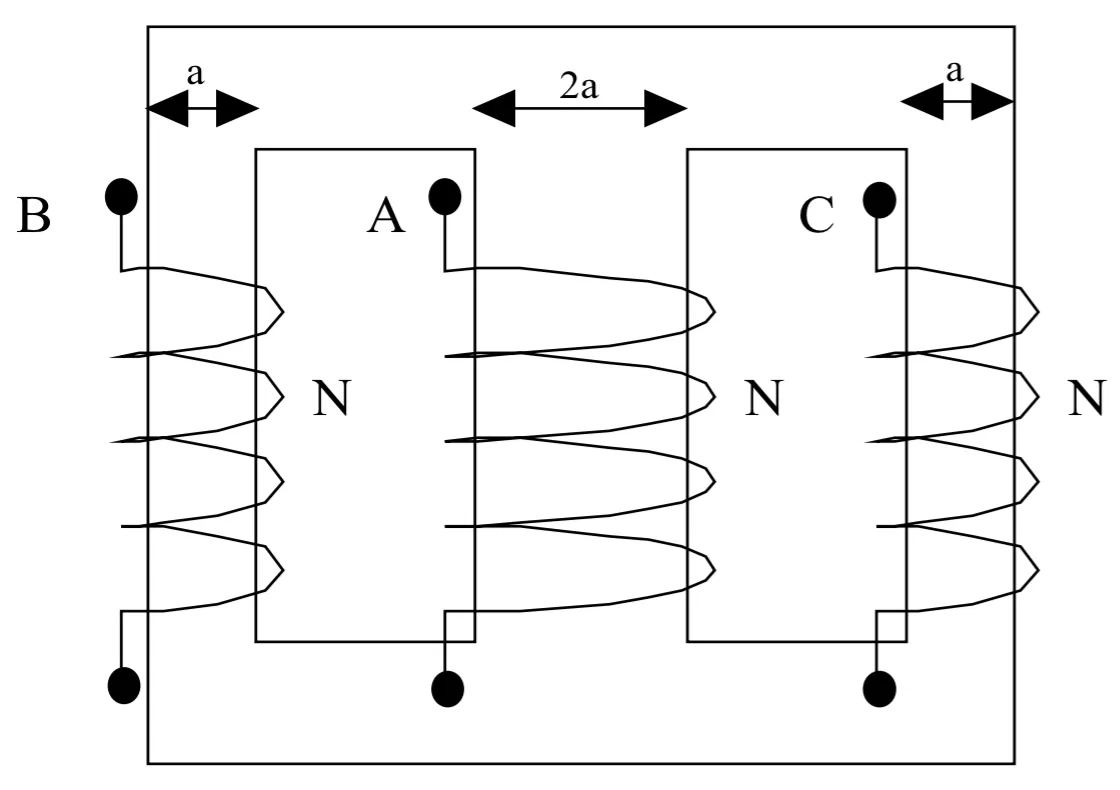

% only consider phase A 
% use minimum number of variables 
% what does N mean?
syms i_A i_B i_C
syms i_dot_A i_dot_B i_dot_C

syms r_A r_B r_C

syms L_AA L_AB L_AC 
syms L_BA L_BB L_BC
syms L_CA L_CB L_CC
% L_AA can be later substituted for magnetizing + leakage 

syms p 
syms lambda_A lambda_B lambda_C
syms lambda_dot_A lambda_dot_B lambda_dot_C


$$\begin{array}{l}
v_{\mathrm{abcs}} =r_s i_{\mathrm{abcs}} +L_s \frac{\partial }{\partial t}\ i_{\mathrm{abcs}} \\
v_{\mathrm{dqns}} =r_s i_{\mathrm{dqns}} +L_s M\frac{\partial }{\partial t}\ i_{\mathrm{abcs}} \\
L_s M\frac{\partial }{\partial t}\ i_{\mathrm{abcs}} =L_s \frac{\partial }{\partial t}\ \left(Mi_{\mathrm{abcs}} \right)-L_s \frac{\partial M}{\partial t}i_{\mathrm{abcs}} \\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;=L_s \frac{\partial }{\partial t}\ i_{\mathrm{dqns}} +L_s \omega \times i_{\mathrm{dqns}} 
\end{array}$$


Since the stationary reference frame is used, $L_s M\frac{\partial }{\partial t}\ i_{\mathrm{abcs}}$ reduces to   


$$L_s M\frac{\partial }{\partial t}\ i_{\mathrm{abcs}} =L_s \frac{\partial }{\partial t}\ {i^s }_{\mathrm{dqns}} +L_s \omega |_{\omega =0} \times \ {i^s }_{\mathrm{dqns}} =L_s \frac{\partial }{\partial t}{i^s }_{\mathrm{dqns}}$$


However, $L_s$ in this context is defined as 


$$L_s =\left(\begin{array}{ccc}
L_{\mathrm{ss}}  & -L_m  & -L_m \\
-L_m  & L_{\mathrm{ss}}  & -L_m \\
-L_m  & -L_m  & L_{\mathrm{ss}} 
\end{array}\right)$$


To decouple d, q, and n axis, we need to diagonalize $L_s$ as follows

% Matrix Ls in its general form named Ltot
Ltot = [
    L_AA L_AB L_AC; 
    L_BA L_BB L_BC;
    L_CA L_CB L_CC
];

% Initialization
Ltot_subs = sym(zeros(3));

% Substitute magnetizing and mutual inductances for L_ss and -L_m
% Note the reference direction for flux 
% is subject to the defined current reference direction

syms L_ss L_m 

% Ltot_subs = subs(Ltot, ...
%     [magnetizingInductance mutualInductances], ...
%     [L_ss L_ss L_ss -L_m -L_m -L_m -L_m -L_m -L_m])

% More efficient method:
% Step 1: Replace diagonal elements with L_ss
diag_indices = logical(eye(size(Ltot))); % Get the logical indices of the diagonal elements
Ltot_subs(diag_indices) = L_ss; % Replace diagonal elements with L_ss

% Step 2: Replace off-diagonal elements with L_m
off_diag_indices = ~diag_indices; % Get the logical indices of the off-diagonal elements
Ltot_subs(off_diag_indices) = -L_m; % Replace off-diagonal elements with L_m

Ltot_subs

$$Ltot\_subs = \left(\begin{array}{ccc} L_{\mathrm{ss}} & -L_{m} & -L_{m}\\ -L_{m} & L_{\mathrm{ss}} & -L_{m}\\ -L_{m} & -L_{m} & L_{\mathrm{ss}} \end{array}\right)$$

### Ldqns Matrix

% [V,D] = eig(A) returns diagonal matrix D of eigenvalues and matrix V 
% whose columns are the corresponding right eigenvectors, 
% so that A*V = V*D.

[V, Ldqns] = eig(Ltot_subs)

$$V = \left(\begin{array}{ccc} 1 & -1 & -1\\ 1 & 1 & 0\\ 1 & 0 & 1 \end{array}\right)$$

$$Ldqns = \left(\begin{array}{ccc} L_{\mathrm{ss}}-2\,L_{m} & 0 & 0\\ 0 & L_{m}+L_{\mathrm{ss}} & 0\\ 0 & 0 & L_{m}+L_{\mathrm{ss}} \end{array}\right)$$

Ltot_subs_reconstructed = V * Ldqns * inv(V)

$$Ltot\_subs\_reconstructed = \left(\begin{array}{ccc} L_{\mathrm{ss}} & -L_{m} & -L_{m}\\ -L_{m} & L_{\mathrm{ss}} & -L_{m}\\ -L_{m} & -L_{m} & L_{\mathrm{ss}} \end{array}\right)$$

*Is Eq. 2.170 in the textbook correct?*

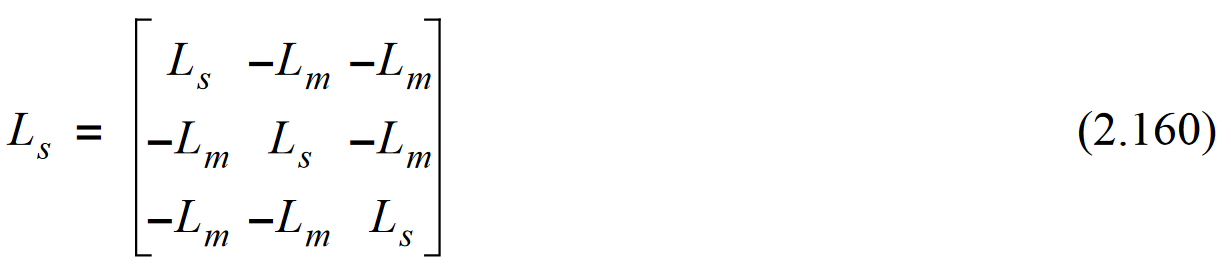

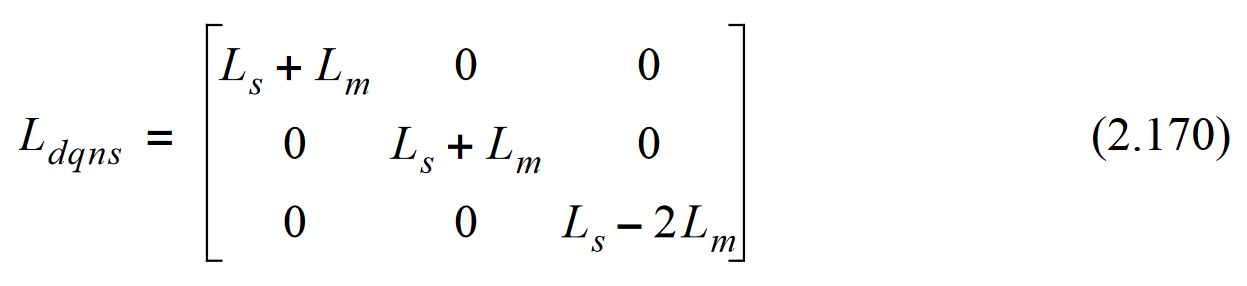

### dqn Voltage Equations 


$${v^s }_{\mathrm{dqns}} =r_s {i^s }_{\mathrm{dqns}} +L_{\mathrm{dqns}} \frac{\partial }{\partial t}{i^s }_{\mathrm{dqns}}$$


syms v__s_ds v__s_qn v__s_ns
syms i__s_ds(t) i__s_qn(t) i__s_ns(t)

vqdns_s = [v__s_ds; v__s_qn; v__s_ns];
iqdns_s = [i__s_ds; i__s_qn; i__s_ns];

dqn_voltage_equations = vqdns_s == Ldqns * diff(iqdns_s,t)

$$dqn\_voltage\_equations(t) = \left(\begin{array}{c} v_{\mathrm{ds}}^{s}=-\frac{\partial }{\partial t}i_{\mathrm{ds}}^{s}\left(t\right)\,\left(2\,L_{m}-L_{\mathrm{ss}}\right)\\ v_{\mathrm{qn}}^{s}=\frac{\partial }{\partial t}i_{\mathrm{qn}}^{s}\left(t\right)\,\left(L_{m}+L_{\mathrm{ss}}\right)\\ v_{\mathrm{ns}}^{s}=\frac{\partial }{\partial t}i_{\mathrm{ns}}^{s}\left(t\right)\,\left(L_{m}+L_{\mathrm{ss}}\right) \end{array}\right)$$

## Problem 3 

Assume the steady state abc variables are of the form where Fa, Fb, and Fc are unequal constants. Show that this unbalanced set of abc variables forms 2-phase balanced sets of qs and ds variables in the arbitrary reference frame with the arguments of (ωet-θ) and (ωet+θ). Note the form of the qs and ds variables when ω=ωe and ω=−ωe.

syms F_a F_b F_c   real positive 
syms omega_e omega real positive 
syms t             real positive 

aa = exp(1i*2*pi/3);

amplitude = [F_a, F_b, F_c];

[Fas, Fbs, Fcs] = get_fa_fb_fc( sqrt(2)*[F_a, F_b, F_c], omega_e )

$$Fas = \sqrt{2}\,F_{a}\,\cos\left(\omega_{e}\,t\right)$$

$$Fbs = \sqrt{2}\,F_{b}\,\cos\left(\frac{2\,\pi }{3}-\omega_{e}\,t\right)$$

$$Fcs = \sqrt{2}\,F_{c}\,\cos\left(\frac{2\,\pi }{3}+\omega_{e}\,t\right)$$


get_fabc = @(fa, fb, fc) fa + aa * fb + aa^2 * fc; 
Fabcs_s = get_fabc( Fas, Fbs, Fcs )

$$Fabcs\_s = \sqrt{2}\,F_{a}\,\cos\left(\omega_{e}\,t\right)+\sqrt{2}\,F_{b}\,\cos\left(\frac{2\,\pi }{3}-\omega_{e}\,t\right)\,\left(-\frac{1}{2}+\frac{\sqrt{3}\,\mathrm{i}}{2}\right)-\sqrt{2}\,F_{c}\,\cos\left(\frac{2\,\pi }{3}+\omega_{e}\,t\right)\,\left(\frac{1}{2}+\frac{\sqrt{3}\,\mathrm{i}}{2}\right)$$


% Option 1:
% % Define the function to return two outputs
% get_fq_fd = @(fqd) deal(real(fqd), -imag(fqd));
% 
% % Call the function with two outputs
% [Fqs, Fds] = get_fq_fd(Fabcs_s)

% Define the function to return a single 1x2 array
get_fq_fd = @(fqd) [real(fqd), -imag(fqd)];

% Call the function and index the outputs
Fqds = get_fq_fd( Fabcs_s * exp(-1i*omega*t) );
Fqs = Fqds(1);
Fds = Fqds(2);

It is seen that unbalanced set of abc variables forms 2-phase balanced sets of qs and ds variables in the arbitrary reference frame with the arguments of (ωe-ω)t and (ωe+ω)t

Fqs = rewrite(simplify(expand(Fqs)),"exp");
Fds = rewrite(simplify(expand(Fds)),"exp");

disp('Fqs: ')

Fqs: 


disp(Fqs)

$$\sqrt{2}\,\left(\frac{F_{a}\,\left(\frac{{\mathrm{e}}^{-t\,\left(\omega -\omega_{e}\right)\,\mathrm{i}}}{2}+\frac{{\mathrm{e}}^{t\,\left(\omega -\omega_{e}\right)\,\mathrm{i}}}{2}\right)}{2}+\frac{F_{b}\,\left(\frac{{\mathrm{e}}^{-t\,\left(\omega -\omega_{e}\right)\,\mathrm{i}}}{2}+\frac{{\mathrm{e}}^{t\,\left(\omega -\omega_{e}\right)\,\mathrm{i}}}{2}\right)}{2}+\frac{F_{c}\,\left(\frac{{\mathrm{e}}^{-t\,\left(\omega -\omega_{e}\right)\,\mathrm{i}}}{2}+\frac{{\mathrm{e}}^{t\,\left(\omega -\omega_{e}\right)\,\mathrm{i}}}{2}\right)}{2}+\frac{F_{a}\,\left(\frac{{\mathrm{e}}^{-t\,\left(\omega +\omega_{e}\right)\,\mathrm{i}}}{2}+\frac{{\mathrm{e}}^{t\,\left(\omega +\omega_{e}\right)\,\mathrm{i}}}{2}\right)}{2}-\frac{F_{b}\,\left(\frac{{\mathrm{e}}^{-t\,\left(\omega +\omega_{e}\right)\,\mathrm{i}}}{2}+\frac{{\mathrm{e}}^{t\,\left(\omega +\omega_{e}\right)\,\mathrm{i}}}{2}\right)}{4}-\frac{F_{c}\,\left(\frac{{\mathrm{e}}^{-t\,\left(\omega +\omega_{e}\right)\,\mathrm{i}}}{2}+\frac{{\mathrm{e}}^{t\,\left(\omega +\omega_{e}\right)\,\mathrm{i}}}{2}\right)}{4}-\frac{\sqrt{3}\,F_{b}\,\left(\frac{{\mathrm{e}}^{-t\,\left(\omega +\omega_{e}\right)\,\mathrm{i}}\,\mathrm{i}}{2}-\frac{{\mathrm{e}}^{t\,\left(\omega +\omega_{e}\right)\,\mathrm{i}}\,\mathrm{i}}{2}\right)}{4}+\frac{\sqrt{3}\,F_{c}\,\left(\frac{{\mathrm{e}}^{-t\,\left(\omega +\omega_{e}\right)\,\mathrm{i}}\,\mathrm{i}}{2}-\frac{{\mathrm{e}}^{t\,\left(\omega +\omega_{e}\right)\,\mathrm{i}}\,\mathrm{i}}{2}\right)}{4}\right)$$


disp('Fds: ')

Fds: 


disp(Fds)

$$\sqrt{2}\,\left(\frac{F_{a}\,\left(\frac{{\mathrm{e}}^{-t\,\left(\omega -\omega_{e}\right)\,\mathrm{i}}\,\mathrm{i}}{2}-\frac{{\mathrm{e}}^{t\,\left(\omega -\omega_{e}\right)\,\mathrm{i}}\,\mathrm{i}}{2}\right)}{2}+\frac{F_{b}\,\left(\frac{{\mathrm{e}}^{-t\,\left(\omega -\omega_{e}\right)\,\mathrm{i}}\,\mathrm{i}}{2}-\frac{{\mathrm{e}}^{t\,\left(\omega -\omega_{e}\right)\,\mathrm{i}}\,\mathrm{i}}{2}\right)}{2}+\frac{F_{c}\,\left(\frac{{\mathrm{e}}^{-t\,\left(\omega -\omega_{e}\right)\,\mathrm{i}}\,\mathrm{i}}{2}-\frac{{\mathrm{e}}^{t\,\left(\omega -\omega_{e}\right)\,\mathrm{i}}\,\mathrm{i}}{2}\right)}{2}+\frac{F_{a}\,\left(\frac{{\mathrm{e}}^{-t\,\left(\omega +\omega_{e}\right)\,\mathrm{i}}\,\mathrm{i}}{2}-\frac{{\mathrm{e}}^{t\,\left(\omega +\omega_{e}\right)\,\mathrm{i}}\,\mathrm{i}}{2}\right)}{2}-\frac{F_{b}\,\left(\frac{{\mathrm{e}}^{-t\,\left(\omega +\omega_{e}\right)\,\mathrm{i}}\,\mathrm{i}}{2}-\frac{{\mathrm{e}}^{t\,\left(\omega +\omega_{e}\right)\,\mathrm{i}}\,\mathrm{i}}{2}\right)}{4}-\frac{F_{c}\,\left(\frac{{\mathrm{e}}^{-t\,\left(\omega +\omega_{e}\right)\,\mathrm{i}}\,\mathrm{i}}{2}-\frac{{\mathrm{e}}^{t\,\left(\omega +\omega_{e}\right)\,\mathrm{i}}\,\mathrm{i}}{2}\right)}{4}+\frac{\sqrt{3}\,F_{b}\,\left(\frac{{\mathrm{e}}^{-t\,\left(\omega +\omega_{e}\right)\,\mathrm{i}}}{2}+\frac{{\mathrm{e}}^{t\,\left(\omega +\omega_{e}\right)\,\mathrm{i}}}{2}\right)}{4}-\frac{\sqrt{3}\,F_{c}\,\left(\frac{{\mathrm{e}}^{-t\,\left(\omega +\omega_{e}\right)\,\mathrm{i}}}{2}+\frac{{\mathrm{e}}^{t\,\left(\omega +\omega_{e}\right)\,\mathrm{i}}}{2}\right)}{4}\right)$$

When ω=ωe and ω=−ωe

omegas = [omega_e -omega_e];

for i = 1:length(omegas)
    thisOmega = omegas(i);
    
    disp(['When omega = ', char(thisOmega), ':'])
    disp('Fqs: ')
    disp(simplify(subs(Fqs, omega, thisOmega)));

    disp('Fqs: ')
    disp(simplify(subs(Fds, omega, thisOmega)));
end

When omega = omega_e:


Fqs: 


$$\frac{\sqrt{2}\,{\mathrm{e}}^{-2\,\omega_{e}\,t\,\mathrm{i}}\,\left(2\,F_{a}-F_{b}-F_{c}-\sqrt{3}\,F_{b}\,\mathrm{i}+\sqrt{3}\,F_{c}\,\mathrm{i}+4\,F_{a}\,{\mathrm{e}}^{2\,\omega_{e}\,t\,\mathrm{i}}+2\,F_{a}\,{\mathrm{e}}^{4\,\omega_{e}\,t\,\mathrm{i}}+4\,F_{b}\,{\mathrm{e}}^{2\,\omega_{e}\,t\,\mathrm{i}}-F_{b}\,{\mathrm{e}}^{4\,\omega_{e}\,t\,\mathrm{i}}+4\,F_{c}\,{\mathrm{e}}^{2\,\omega_{e}\,t\,\mathrm{i}}-F_{c}\,{\mathrm{e}}^{4\,\omega_{e}\,t\,\mathrm{i}}+\sqrt{3}\,F_{b}\,{\mathrm{e}}^{4\,\omega_{e}\,t\,\mathrm{i}}\,\mathrm{i}-\sqrt{3}\,F_{c}\,{\mathrm{e}}^{4\,\omega_{e}\,t\,\mathrm{i}}\,\mathrm{i}\right)}{8}$$

Fqs: 


$$\frac{\sqrt{2}\,{\mathrm{e}}^{-2\,\omega_{e}\,t\,\mathrm{i}}\,\left(2\,F_{a}\,\mathrm{i}-F_{b}\,\mathrm{i}-F_{c}\,\mathrm{i}+\sqrt{3}\,F_{b}-\sqrt{3}\,F_{c}-2\,F_{a}\,{\mathrm{e}}^{4\,\omega_{e}\,t\,\mathrm{i}}\,\mathrm{i}+F_{b}\,{\mathrm{e}}^{4\,\omega_{e}\,t\,\mathrm{i}}\,\mathrm{i}+F_{c}\,{\mathrm{e}}^{4\,\omega_{e}\,t\,\mathrm{i}}\,\mathrm{i}+\sqrt{3}\,F_{b}\,{\mathrm{e}}^{4\,\omega_{e}\,t\,\mathrm{i}}-\sqrt{3}\,F_{c}\,{\mathrm{e}}^{4\,\omega_{e}\,t\,\mathrm{i}}\right)}{8}$$

When omega = -omega_e:


Fqs: 


$$\sqrt{2}\,\left(\frac{F_{a}}{2}-\frac{F_{b}}{4}-\frac{F_{c}}{4}+\frac{F_{a}\,\left(\frac{{\mathrm{e}}^{-2\,\omega_{e}\,t\,\mathrm{i}}}{2}+\frac{{\mathrm{e}}^{2\,\omega_{e}\,t\,\mathrm{i}}}{2}\right)}{2}+\frac{F_{b}\,\left(\frac{{\mathrm{e}}^{-2\,\omega_{e}\,t\,\mathrm{i}}}{2}+\frac{{\mathrm{e}}^{2\,\omega_{e}\,t\,\mathrm{i}}}{2}\right)}{2}+\frac{F_{c}\,\left(\frac{{\mathrm{e}}^{-2\,\omega_{e}\,t\,\mathrm{i}}}{2}+\frac{{\mathrm{e}}^{2\,\omega_{e}\,t\,\mathrm{i}}}{2}\right)}{2}\right)$$

Fqs: 


$$-\sqrt{2}\,\left(\frac{\sqrt{3}\,F_{c}}{4}-\frac{\sqrt{3}\,F_{b}}{4}+\frac{F_{a}\,\left(\frac{{\mathrm{e}}^{-2\,\omega_{e}\,t\,\mathrm{i}}\,\mathrm{i}}{2}-\frac{{\mathrm{e}}^{2\,\omega_{e}\,t\,\mathrm{i}}\,\mathrm{i}}{2}\right)}{2}+\frac{F_{b}\,\left(\frac{{\mathrm{e}}^{-2\,\omega_{e}\,t\,\mathrm{i}}\,\mathrm{i}}{2}-\frac{{\mathrm{e}}^{2\,\omega_{e}\,t\,\mathrm{i}}\,\mathrm{i}}{2}\right)}{2}+\frac{F_{c}\,\left(\frac{{\mathrm{e}}^{-2\,\omega_{e}\,t\,\mathrm{i}}\,\mathrm{i}}{2}-\frac{{\mathrm{e}}^{2\,\omega_{e}\,t\,\mathrm{i}}\,\mathrm{i}}{2}\right)}{2}\right)$$

function [fa, fb, fc] = get_fa_fb_fc(amplitude, frequency)
    syms t real positive 
    fa = amplitude(1) * cos( frequency * t );
    fb = amplitude(2) * cos( frequency * t - 2*pi/3 );
    fc = amplitude(3) * cos( frequency * t + 2*pi/3 );
end 

## Appendix

segments = {'A', 'B', 'C'};
otherLegs = setdiff(segments, 'A') % `seg1` could be 'A', 'B', or 'C'

otherLegs = 1×2 cell array
    {'B'}    {'C'}



% strcmp

% resistances = [r_A; r_B; r_C];
% 
% currents_a_b_c = [i_A; i_B; i_C];
% currents_dot_a_b_c = [i_dot_A; i_dot_B; i_dot_C];
% 
inductances = ...
[
    L_AA L_AB L_AC; 
    L_BA L_BB L_BC;
    L_CA L_CB L_CC
];
% 
% fluxLinkages = [lambda_A; lambda_B; lambda_C];
% fluxLinkages_dot = [lambda_dot_A; lambda_dot_B; lambda_dot_C];
% 
% voltage_a_b_c = currents_a_b_c .* resistances + fluxLinkages_dot;
% disp('Voltage equations in abc are: ')
% disp(voltage_a_b_c)

% fluxLinkages_dot_a_b_c = inductances * currents_dot_a_b_c;
% disp('Flux linkage equations in abc are: ') 
% disp(fluxLinkages_dot_a_b_c) % ignore bars on top of symbols; they make no difference 

% voltage_a_b_c = subs( voltage_a_b_c, fluxLinkages_dot, fluxLinkages_dot_a_b_c );
% disp('Voltage equations substituted by flux linkage equations in abc are: ')
% disp(voltage_a_b_c)

% % Solve for the matrix form
% syms v_A v_B v_C
% voltages = [v_A; v_B; v_C];
% 
% % symvar(voltage_eqns_abc == voltages)
% 
% pCurrents = p*currents_a_b_c;
% 
% [A, b] = equationsToMatrix(voltage_a_b_c == voltages, currents_dot_a_b_c);
% disp('Matrix form of the system:');
% disp(A);
% disp(b);

### abc to dqn Transformation Matrix 

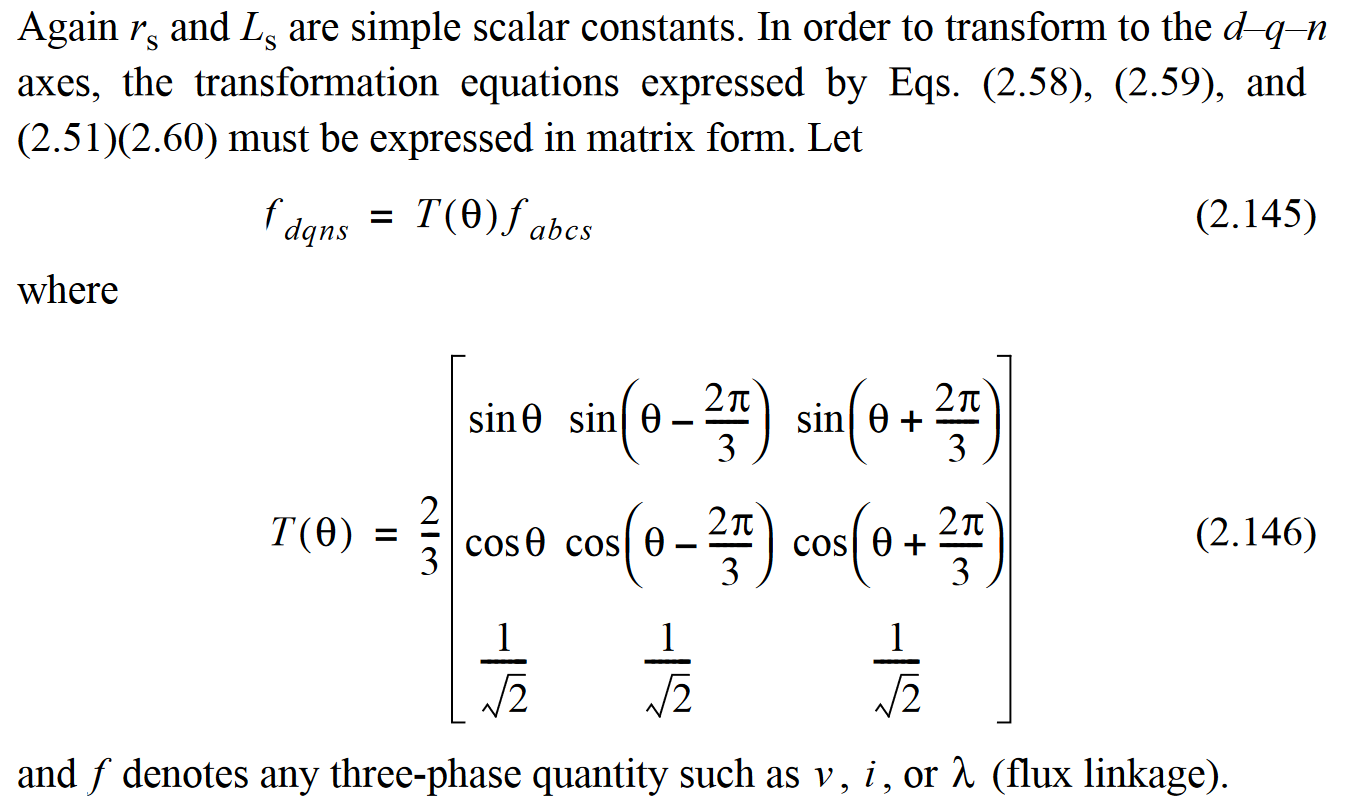

syms T_abc2dq(theta) 

phi = 2*pi/3;
T_abc2dq(theta) = 2/3 * [ ...
    sin(theta) sin(theta-phi) sin(theta+phi);
    cos(theta) cos(theta-phi) cos(theta+phi);
     1/sqrt(2)      1/sqrt(2)      1/sqrt(2)
];
disp('abc to dqn Transformation Matrix: ')

abc to dqn Transformation Matrix: 


disp(T_abc2dq(theta))

$$\left(\begin{array}{ccc} \frac{2\,\sin\left(\theta \right)}{3} & \frac{2\,\sin\left(\theta -\frac{2\,\pi }{3}\right)}{3} & \frac{2\,\sin\left(\theta +\frac{2\,\pi }{3}\right)}{3}\\ \frac{2\,\cos\left(\theta \right)}{3} & \frac{2\,\cos\left(\theta -\frac{2\,\pi }{3}\right)}{3} & \frac{2\,\cos\left(\theta +\frac{2\,\pi }{3}\right)}{3}\\ \frac{\sqrt{2}}{3} & \frac{\sqrt{2}}{3} & \frac{\sqrt{2}}{3} \end{array}\right)$$


U = sym(ones(3,3))

$$U = \left(\begin{array}{ccc} 1 & 1 & 1\\ 1 & 1 & 1\\ 1 & 1 & 1 \end{array}\right)$$

T_abc2dq(0) * U / T_abc2dq(0)

$$ans = \left(\begin{array}{ccc} 0 & 0 & 0\\ 0 & 0 & 0\\ 0 & 0 & 3 \end{array}\right)$$


% Alternatives
% T_abc2dq(0)^(-1) = inv(T_abc2dq(0))
% U * inv(T_abc2dq(0)) = U / T_abc2dq(0)

### abc to dqn to Transformation 

% theta = 0: stationary reference frame 
% theta = ω: arbitrary reference frame 
% theta = ωr: rotor reference frame 
% theta = ωe: synchronous reference frame 

% voltage_eqns_dqn = T_abc2dq(0) * voltage_a_b_c;
% disp('Voltage equations in stationary dqn are: ')
% disp(voltage_eqns_dqn)

% syms r_s 
% vars_resistance = [r_A r_B r_C];
% VARS_resistance = [r_s r_s r_s];
% 
% syms i_abc i_dot_abc [3 1] matrix 
% syms L_matrix [3 3] matrix 
% voltage_abc = r_s * i_abc + L_matrix * i_dot_abc;
% 
% disp('Voltage equation in single-line abc: ')
% disp(voltage_abc)
% 
% vv = subs(voltage_abc, ...
%     {L_matrix, i_abc, i_dot_abc}, ...
%     {inductances, currents_a_b_c, currents_dot_a_b_c})


% magnetizingInductances = [L_AA L_BB L_CC];
% mutualInductances = [L_AB L_AC L_BA L_BC L_CA L_CB];
% 
% Ls = diag(magnetizingInductances) 
% Lm = Ltot - Ls
% 
% Ltot * eye(3)
% Lm * ones(1)
% 
% eye(3)